# Setup and Calibrate Electric Motor Kit for Rapid Control Prototyping

## RCP Demo Setup

The Electric Motor Control kit was designed to be used with a Speedgoat target computer equipped with a [IO397 FPGA I/O Module](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-i-o-modules-io397) and enable rapid protoyping of your Simulink contols. 

Proceed as follows to setup the Electric Motor Kit for RCP purposes: 

- Connected the Electric Motor Control with the IO397 by using the M12 cables provided (see image below). 

- Connect the 3-phase inverter power supply 

- Brushless DC motor power phases and encoder sensor cables should be connected to the 3-phase inverter by default

- Setup Speedgoat target computer as defined in the Quick Start Guide supplied in the Customer Portal: [**speedgoat.com/login**](https://speedgoat.com/login)

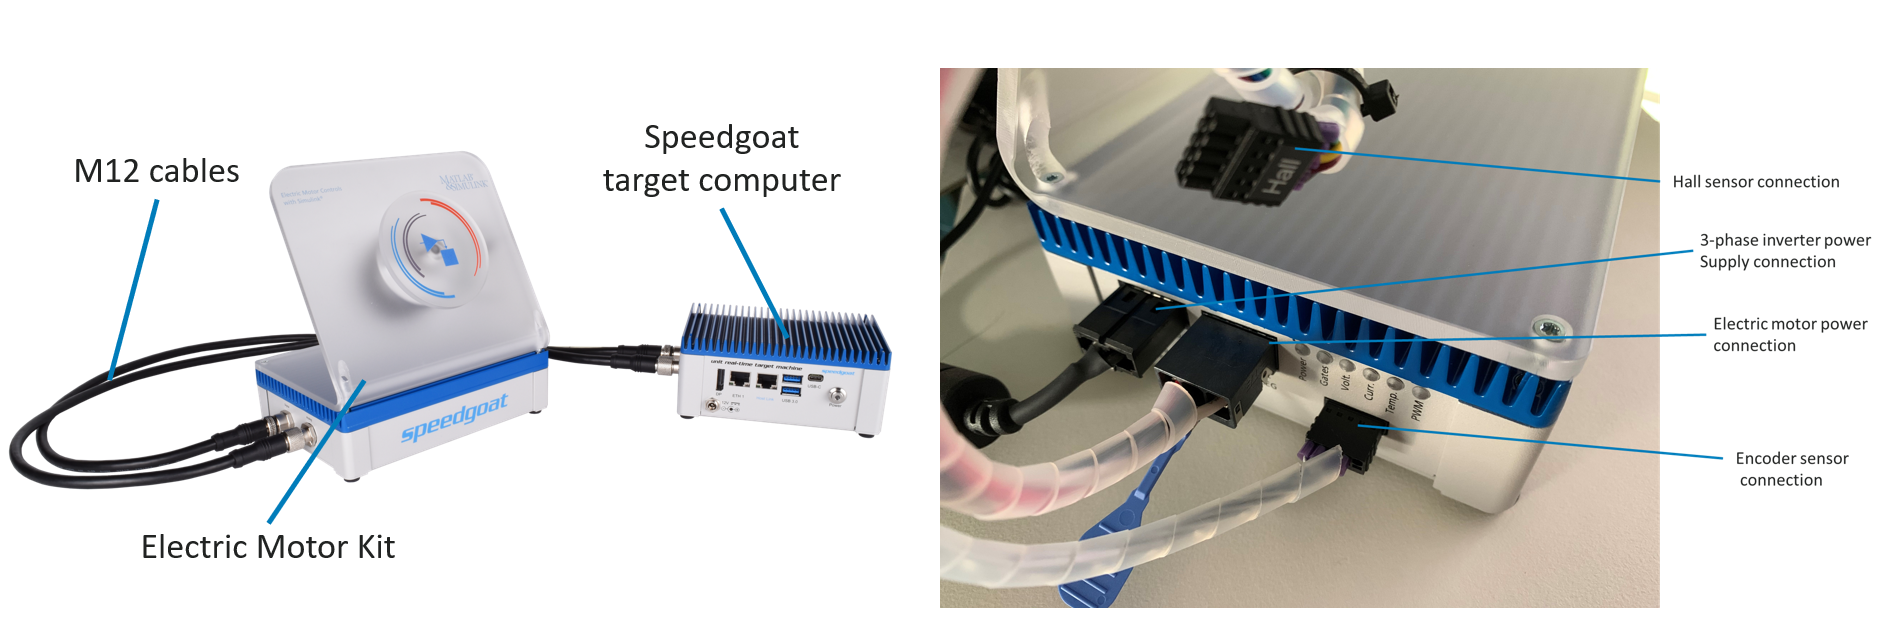

### Optimize Simulink Real-Time RTOS performance

To maximize real-time application performance and enable 20kHz closed-loop rates Simulink Real-Time RTOS needs to run with 'Graphics mode' disabled.

At the MATLAB command prompt type **speedgoat.kernelTransfer**. With this command a graphical user interface is opened which allows the kernel image to be configured and transferred to the target machine.

Disable graphics mode and transfer [new kernel](https://www.speedgoat.com/help/slrt/page/configuration/refentry_target_setup) to the target computer

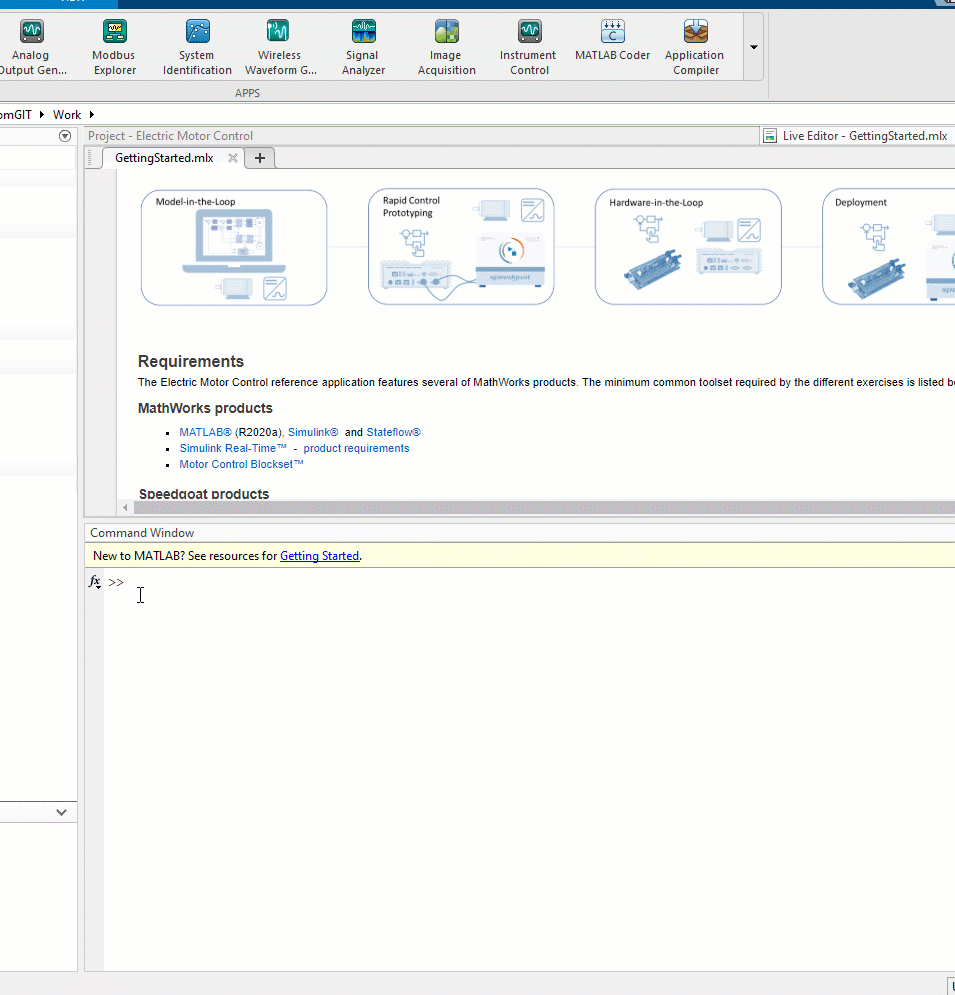

## Calibrate ADCs for Phase Current Feedback

Electic Motor Control Kit used ADCs to measure phase current as feedback in the current control algorithm. Due to manufacturing variability, each kit can have some difference in ADC Offset (voltage at zero current). This exercise shows how to identify right value for the ADC offset.

### Open Real-Time Model

Open Model

mdl = 'FieldOrientedController_RCP';
open_system(mdl);
switchConfig('RCP');
switchMotorKit('SG_Inverter_RCP_Kit'); % 'TI_Inverter_RCP_Kit'

Select Signal Editor Experiment

set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs 
set_param([mdl,'/SignalEditor_Experiments'],'ActiveScenario','Calibrate_ADC_Offset'); % Select Experiment

### Build and Download

rtwbuild(mdl);

### Run and Plot Logged Data

tg = slrt;
load(tg,mdl);
tg.start;pause(5);tg.stop;
runObj = Simulink.sdi.Run.getLatest;
motMeas = getSignalsByName(runObj,'controllerFeedback');
transducerVoltages = motMeas.Values.transducerVoltage.Data;
plot(transducerVoltages);
avgTransducerVoltages = sum(transducerVoltages)/length(transducerVoltages)  

### Update ADC Offset Values at Zero Current

#### Update Offset Values in Plant Data Dictionary

dd = Simulink.data.dictionary.open('SGKitPlantData.sldd');
adcStruct = getValue(getEntry(dd.getSection('Design Data'),'adc'));
adcStruct.Value.TransducerVoltAtZeroAmpere
adcStruct.Value.TransducerVoltAtZeroAmpere = avgTransducerVoltages;
setValue(getEntry(dd.getSection('Design Data'),'adc'),adcStruct);

#### Update Offset Values in Controller Data Dictionary

dd = Simulink.data.dictionary.open('SGKitControllerData.sldd');
getValue(getEntry(dd.getSection('Design Data'),'paramAdcTransducerVoltAtZeroAmpere'));
setValue(getEntry(dd.getSection('Design Data'),'paramAdcTransducerVoltAtZeroAmpere'),avgTransducerVoltages);

### Restore Model and Close

close_system(mdl,0);